clc
clear

load('labeled_tree_coordinates_firms.mat');

%signatures = convxy(:,4:50);
%signatures = convxy(:,35:50);
signatures = convxy(:,4:35);
labels = convxy(:,3);

c = cvpartition(labels, "HoldOut",0.20);

training_idx = training(c);
testing_idx = test(c);

training_signatures = signatures(training_idx,:);
testing_signatures = signatures(testing_idx,:);

training_labels = labels(training_idx,:);
testing_labels = labels(testing_idx,:);

% Random Forest training
numTrees = 500; % Increase the number of trees
RFmodel = TreeBagger(numTrees, training_signatures, training_labels, 'Method', 'classification', 'OOBPrediction', 'on');

% Predict classes on test data
[idx_rf,scores] = predict(RFmodel, testing_signatures);

% Conversione delle etichette di test e delle previsioni in array numerici
idx_rf = cellfun(@str2double, idx_rf);
% Calcolo della matrice di confusione per la label 0
[C_0, order_0] = confusionmat(testing_labels(testing_labels == 0 | idx_rf == 0), idx_rf(testing_labels == 0 | idx_rf == 0));

% Calcolo della matrice di confusione per la label 1
[C_1, order_1] = confusionmat(testing_labels(testing_labels == 1 | idx_rf == 1), idx_rf(testing_labels == 1 | idx_rf == 1));

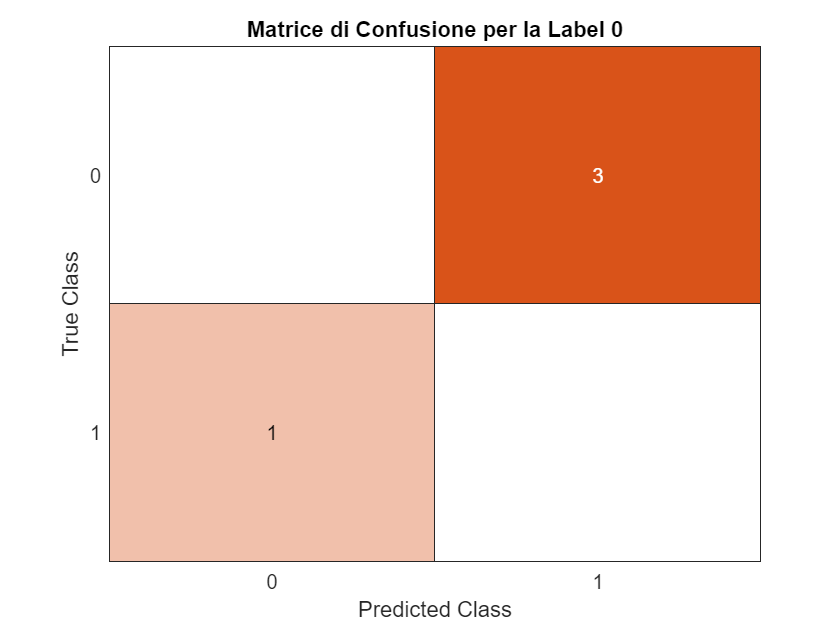

% Plot della matrice di confusione per la label 0
figure;
confusionchart(C_0, order_0);
title('Matrice di Confusione per la Label 0');

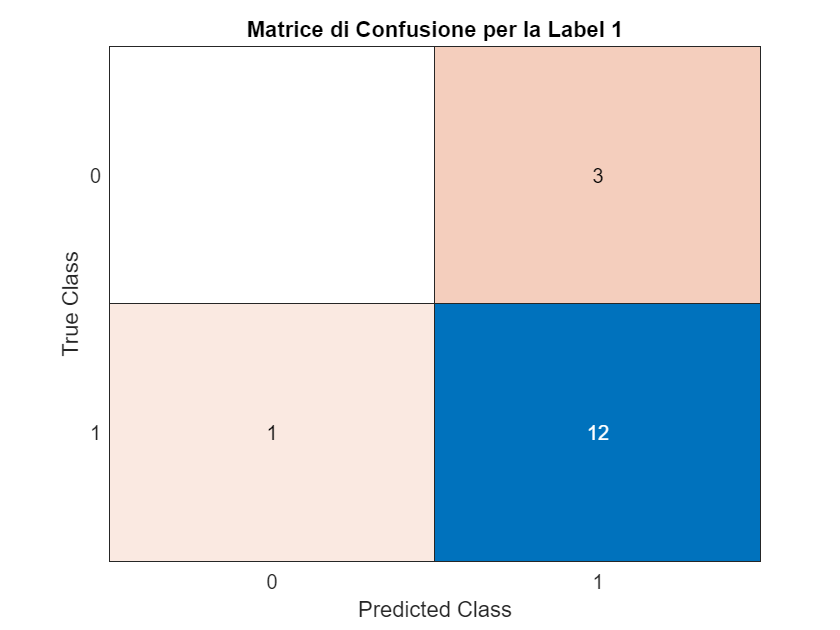


% Plot della matrice di confusione per la label 1
figure;
confusionchart(C_1, order_1);
title('Matrice di Confusione per la Label 1');